## visualizing pre-filtering/processing

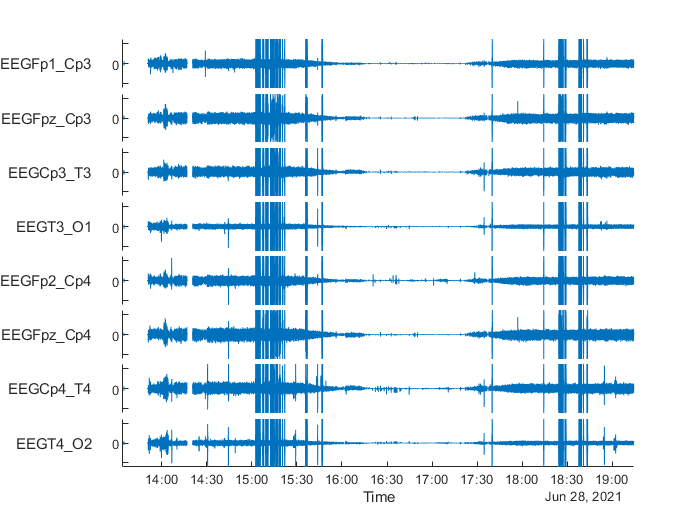

% visualizing entire dataset
stackedplot(allEDFs.data{'EEG'});

## filtering out signal saturation periods

% signals that are above a certain threshold (abs(50)) will be changed to NaN.
    % Note: this threshold may need to be changed to another value. test
    % with multiple datasets to find the one that works the best.

allEDFs_filtered = allEDFs; % save allEDFs to another cell table

table_size = size(allEDFs_filtered.data{'EEG'}); % determine size of table for for loop

% find saturation indices
saturation_indx1 = find(abs(allEDFs_filtered.data{'EEG'}{:, 1}) > 100); 
saturation_indx2 = find(abs(allEDFs_filtered.data{'EEG'}{:, 4}) > 100); 

% known datapoints outside of saturation threshold
allEDFs_filtered.data{'EEG'}{saturation_indx1(1,1), 1} 

ans = -108.3952

allEDFs_filtered.data{'EEG'}{saturation_indx1(2,1), 1}

ans = 102.6795

allEDFs_filtered.data{'EEG'}{saturation_indx2(1,1), 4} 

ans = -122.7405


% replace saturated datapoints with NaN
for i = 1:table_size(1,2)
    allEDFs_filtered.data{'EEG'}{(abs(allEDFs_filtered.data{'EEG'}{:,i}) > 50),i} = NaN;
end

% check that known datapoints are now "NaN"
allEDFs_filtered.data{'EEG'}{saturation_indx1(1,1), 1} % check that known datapoint is now "NaN"

ans = NaN

allEDFs_filtered.data{'EEG'}{saturation_indx1(2,1), 1} 

ans = NaN

allEDFs_filtered.data{'EEG'}{saturation_indx2(1,1), 4}

ans = NaN

% Note: checking that the saturated indices are changed to NaN should
% eventually become a part of unit testing, where a much larger number of
% values are checked. what might be a good idea is to test a few values
% consistently each time and have another few tests that check random
% values from the saturation_indx* matrices  


## remove common noise features


    % question - should we normalize the data and change it to the most
    % common occuring value as "zero", for example, treat 0.0013 as if it
    % is zero?
    
    % otherwise, we would just not count those values in the analysis -
    % change them to NaN
    
    common_value = mode(allEDFs_filtered.data{'EEG'}{:,:})  % find indices of most common value

common_value =     0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013


    common_indices = find(allEDFs_filtered.data{'EEG'}{:,:} == common_value); % finding the most common value in the timetable
    % replacing all indices with "common_value"
%     for i = 1:table_size(1,2)
%     allEDFs_filtered.data{'EEG'}{(allEDFs_filtered.data{'EEG'}{:,i}) == common_value(1,1),i} = NaN;
%     end
    

## OR

    % normalizing to "common_value"    
%     for i = 1:table_size(1,2)
%         allEDFs_filtered.data{'EEG'}{:,i} = allEDFs_filtered.data{'EEG'}{:,i} - common_value(1,i);
%     end
       

## OR

% search for other instances of "commmon values" in other case. it may not
% always be the same value as the most often occuring value
% window in 15 second segments, check for common value, then see if the
% occurances of that common value is more than x% in a given window. if so,
% replace those values with NaN. 


## OR

% window as above statement, keep track of them in a table, first column is
% the common value in the window, second is number of occurences of that
% common value in the window. then we can replace instances of common
% values throughout the case with NaN
rows_per_record = allEDFs_filtered.info{'EEG'}.NumSamples(1);    
sample_rate = rows_per_record/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration);   
window_size = sample_rate * 15;

window_inds_filter = 1:window_size:size(allEDFs_filtered.data{'EEG'}(:,1)); % start from beginning of dataset
% window_filter = zeros(window_size, length(channels(1,:)), length(window_inds_filter));    % preallocating for speed
for i = 1:length(window_inds_filter)-1
     % find most common value in 15 second window
     dataset_window = allEDFs_filtered.data{'EEG'}{window_inds_filter(1,i):window_inds_filter(1,i)+window_size-1,:};
     window_filter_data(i,:) = mode(dataset_window); 
    % find number of common occurances within each 15 second window
    % rows returns the row that mode is found in, columns returns the
    % EEG channel that mode is found in (1:8)
    [rows, columns]  = find(dataset_window == window_filter_data(i,:));
    found_mode_values{i,1} = [rows columns];
    if (isnan(found_mode_values{i,1})) % 
        continue;
    end
    [B, BG, BP] = groupcounts(found_mode_values{i,1}(:,2));
    
    if (BG(B>=5)) % if percentage of occurances of mode exceed threshold, 
        % replace all occurances within window with NaN
        dataset_window(found_mode_values{i,1}(:,1), found_mode_values{i,1}(:,2)) = NaN;         
    end
end

Unable to perform assignment because brace indexing is not supported for variables of this type.

## OR


%scan thru data, find starting and ending points that are above a certain
%threshold, set to NaN. run a loop to check next values. start tallying
%values that are similar, when they change to a certain threshold, replace
%those values with NaN and restart the tally



## visualize post-filtering/processing

%y = stackedplot(allEDFs_filtered.data{'EEG'}) % visualizing post-filtering
%y.AxesProperties(1).YLimits = [-200 200];




## save preprocessed dataset to a new file that will be called in later scripts

% TODO: